% imshow("map1.png")
% hold on
% [xi,yi] = getpts();
% Path = [xi yi];
Path = [0 0;1 1;2 2;3 3; 4 4; 5 5; 6 6; 7 7; 8 8; 9 9; 10 10; 11 11];
M_k = [1 / 6, 4 / 6, 1 / 6, 0;
    -3 / 6, 0, 3 / 6, 0;
    3 / 6, -6 / 6, 3 / 6, 0;
    -1 / 6, 3 / 6, -3 / 6, 1 / 6 ];
A = M_k(1,:);
for i = 2:size(Path,1)
    B = A(end,:);
    A = [A,zeros(i - 1,1)];
    A = [A;0,B];
end
A = [A;zeros(1,size(Path,1) - 1),M_k(2,:)];
A = [A;M_k(2,:),zeros(1,size(Path,1) - 1)];
A = [A;zeros(1,size(Path,1)-1),M_k(3,:)];
A = [A;M_k(3,:),zeros(1,size(Path,1) - 1)];
b = [Path;0,0;0 0;0 0;0 0];
H = zeros(size(Path,1)+3);
H(1,1) = 1;
H(end,end) = 1;
H(2,2) = 5;
H(end-1,end-1) = 5;
for i= 3:size(Path,1)+1
    H(i,i) = 6;
end
BsplineControlPoint = zeros(size(Path,1)+3,2); 
BsplineControlPoint(:,1) = quadprog(H,zeros(size(Path,1)+3,1),[],[],A,b(:,1));


求解器过早停止。

quadprog 已停止，因为它超过迭代限制，
options.MaxIterations = 2.000000e+02。



BsplineControlPoint(:,2) = quadprog(H,zeros(size(Path,1)+3,1),[],[],A,b(:,2));


求解器过早停止。

quadprog 已停止，因为它超过迭代限制，
options.MaxIterations = 2.000000e+02。



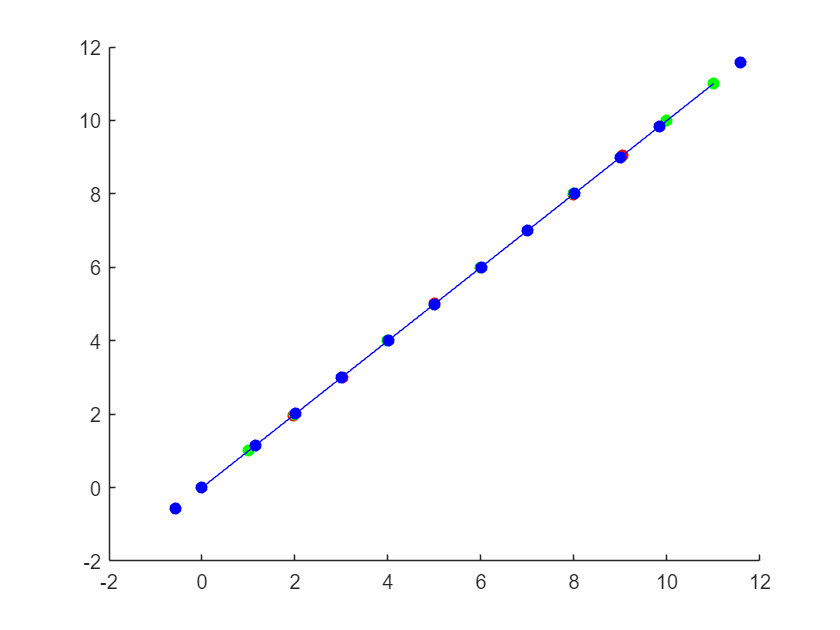

scatter(BsplineControlPoint(:,1),BsplineControlPoint(:,2),"filled",'r')
hold on
scatter(Path(:,1),Path(:,2),"filled",'g')


[x, y] = GetTrajectory( BsplineControlPoint,4);
plot(x,y,'r')
hold on

OptimizedControlPos = BsplineControlPoint;
for p = 4:size(BsplineControlPoint,1) - 4
    OptimizedControlPos(p,:) =OptimizedControlPos(p,:) + (BsplineControlPoint(p - 1,:) - BsplineControlPoint(p,:)) * 0.2  + (BsplineControlPoint(p + 1,:) - BsplineControlPoint(p,:)) * 0.2 ;
end

scatter(OptimizedControlPos(:,1),OptimizedControlPos(:,2),"filled",'b')
hold on
[x, y] = GetTrajectory( OptimizedControlPos,4);
plot(x,y,'b')
hold on